## Esempio serbatoio (significato dei poli).

Dati problema.

clc
clear

rs_m = 1; % Raggio serbatoio[m].
sSerb = pi*rs_m^2; % Superficie serbatoio [m^2].

rfOut_m = 0.05; % Raggio foro di uscita [m].
sfOut = pi*rfOut_m^2; % Superficie foro di uscita [m^2].

g_acc = 9.81; % Accelerazione di gravità [m/s^2].

Definizione del **numeratore** e del **denominatore** della **FdT H(s)**.

- La **FdT** presenta un polo nell’origine. Infatti il sistema ha un unico elemento in grado di accumulare energia utile all’evoluzione del sistema: il contenitore cilindrico. Esso immagazzina l’energia sotto forma di liquido accumulato nel serbatoio che determina un innalzamento del livello del liquido.

- Se ipotizziamo che **H** è molto grande, che i tempi di osservazione della dinamica sono limitati e che **p(t)** è sufficientemente piccolo, possiamo ritenere questo modello astratto perfettamente descrittivo della dinamica del sistema.

num = 1;
den = [sSerb 0];

sys = tf(num,den)


sys =
 
     1
  -------
  3.142 s
 
Continuous-time transfer function.
Model Properties


Risposta a gradino del sistema (senza foro di uscita).

- La **risposta a gradino** non può che essere un rampa lineare, con pendenza inversamente proporzionale alla sezione **s = πr^2** del cilindro.

- L’energia viene sempre accumulata e mai dissipata. È evidente che il sistema è instabile, il transitorio non si estingue mai e il regime permanente non viene mai raggiunto.

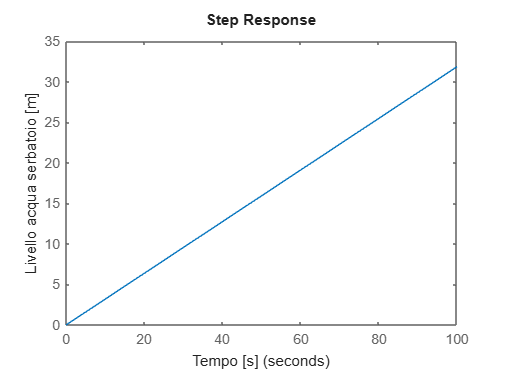

pIngr = 1; % Portata in ingresso del serbatoio [m^3/s].
tStep = 100; % Tempo step [s].

stepCfg = RespConfig('StepAmplitude',pIngr);
step(sys,tStep,stepCfg)

xlabel("Tempo [s]")
ylabel("Livello acqua serbatoio [m]");

Portata foro di uscita (non lineare).

- Si ipotizza un serbatoio che si riempie da 0 fino ad un certo valore predefinito, e se ne monitora la portata tramita il foro in uscita di raggio **rf**.

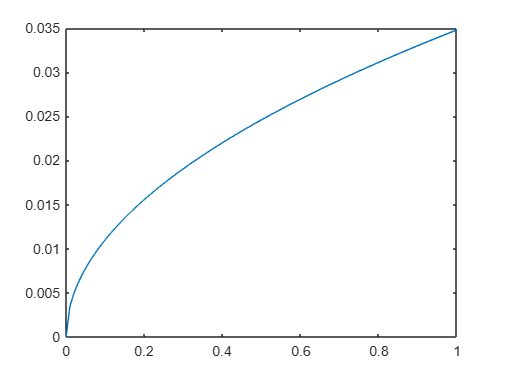

hwLim_m = 1; % Livello massimo raggiunto dall'acqua durante la simulazione [m].
hw_m = linspace(0,hwLim_m); % Livello dell'acqua nel serbatoio [m].
pfOut_nl = sfOut*sqrt(2*g_acc*hw_m); % Portata foro di uscita [m^3/s] (non lineare).

plot(hw_m,pfOut_nl,"DisplayName","Portata foro uscita non linearizzata");
hold on

Portata foro di uscita (linearizzata).

- Linearizzazione dell'equazione differenziale: si deve trovare un punto di equilibrio di funzionamento (lez 85, p 12) che mette in relazione la portata in ingresso con quella di uscita: pfOut_lin(pIn,rfOut_m) = m*hw_m.

- Il **Punto di Equilibrio** indica il punto in cui il livello dell'acqua [m] si stabilizza e quindi la portata in ingresso si equivale con quella di uscita. Questo è dato dal fatto che la portata in ingresso è costante, mentre quella in uscita (supponendo il raggio del foro in uscita costante) dipende dall'altezza del livello dell'acqua, come indicato dalla legge di Torricelli (all'aumentare del livello dell'acqua, aumenta anche la velocità di uscita dell'acqua e di conseguenza la portata). 

pIn = 0.03; % Portata in ingresso [m^3/s].
m_num = 2*g_acc*sfOut^2; % Numeratore coeff. ang. m.
m_den = pIn; % Denominatore coeff. ang. m.
m = m_num/m_den; % Coefficiente Angolare m.

hEq = m_den^2/m_num % Punto di equilibrio del livello dell'acqua [m].

hEq = 0.7436

pEq = sfOut*sqrt(2*g_acc*hEq) % Punto di equilibrio della portata dell'acqua [m^3/s].

pEq = 0.0300

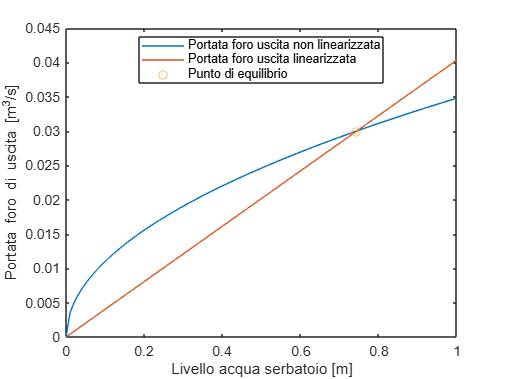

                              % NOTA: per hEq si ha pEq = pIn (come ci si aspettava).

pfOut_lin = m*hw_m; % Portata foro di uscita [m^3/s] (linearizzata).

plot(hw_m,pfOut_lin,"DisplayName", "Portata foro uscita linearizzata")
hold on
plot(hEq,pEq,"o","DisplayName","Punto di equilibrio");
hold off

legend("Location","best")
xlabel("Livello acqua serbatoio [m]");
ylabel("Portata foro di uscita [m^3/s]");

Risposta a gradino del sistema linearizzato (con foro di uscita).

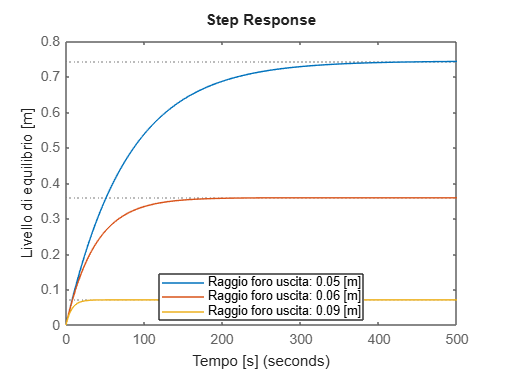

A = 0.03; % Ampiezza gradino [m^3/s]

rfOut_m = [0.05, 0.06, 0.09]; % Raggio foro di uscita [m].

for i = 1:length(rfOut_m)
    a0 = (2*g_acc*(pi^2)*(rfOut_m(i)^4))/A;
    a1 = sSerb;
    
    K = 1/a0;
    Tau = a1/a0;
    
    num_lin = K; % Sostituendo K con 1, si ottiene il grafico della dispensa.
    den_lin = [Tau 1];
    
    sys_lin = tf(num_lin,den_lin);
    
    stepCfg = RespConfig('StepAmplitude',A);
    step(sys_lin,stepCfg)
    hold on
    
end

    legend("Raggio foro uscita: " + num2str(rfOut_m(1) + " [m]"), ...
           "Raggio foro uscita: " + num2str(rfOut_m(2) + " [m]"), ...
           "Raggio foro uscita: " + num2str(rfOut_m(3) + " [m]"));
    legend("Location","best");
    xlabel("Tempo [s]");
    ylabel("Livello di equilibrio [m]");

hold off